# **Project#1: EngineFaultDB - Feature Extraction**

**Class: Industrial AI & Automation**

**Author: GYEONHEAL AN(21900416), GARMA JIN(21900xxx)**

**Contents**

**1. Data Prepartion**

**2. Data Preprocessing**

-     결측치 확인

-     이상치 확인

-     Correlation Check

-     Min-Max Scaling

**3. Feature Extraction**

- Time-Domain Feature Extraction

- Freq-Domain Feature Extraction

addpath("../../../Library");

## 1. Data Prepartion

clc; clear; close all;

Data_location = "../Datasets/EngineFaultDB_Final.xlsx";
Engine_datasets = readtable(Data_location, 'VariableNamingRule', 'preserve');

% Sampling Freq
fs = 10;
Engine_datasets.Properties

ans =   TableProperties - 속성 있음:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Fault'  'MAP'  'TPS'  'Force'  'Power'  'RPM'  'Consumption L/H'  'Consumption L/100KM'  'Speed'  'CO'  'HC'  'CO2'  'O2'  'Lambda'  'AFR'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: 사용자 지정 속성을 설정하지 않았습니다.
 addprop 및 rmprop을(를) 사용하여 CustomProperties를 수정하십시오.


**Time - Domain Analysis**

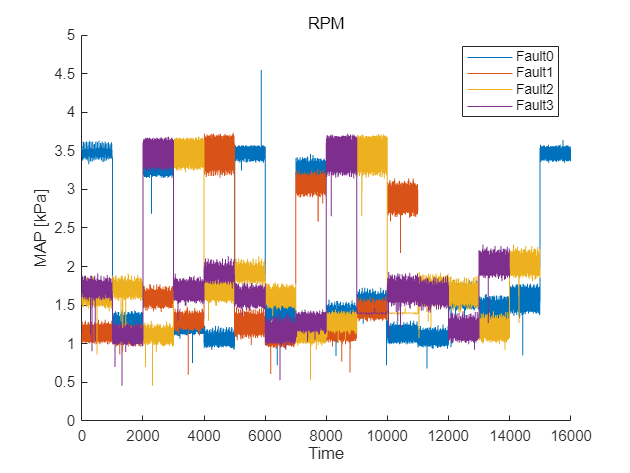

% Data Length Configuration
L0 = height(find(Engine_datasets.Fault == 0)); % Fault 0 : 16,000
L1 = height(find(Engine_datasets.Fault == 1)); % Fault 1 : 10,988
L2 = height(find(Engine_datasets.Fault == 2)); % Fault 2 : 15,000
L3 = height(find(Engine_datasets.Fault == 3)); % Fault 3 : 14,001

figure;
hold on;
plot((1:L0), Engine_datasets(Engine_datasets.Fault == 0, :).MAP);
plot((1:L1), Engine_datasets(Engine_datasets.Fault == 1, :).MAP);
plot((1:L2), Engine_datasets(Engine_datasets.Fault == 2, :).MAP);
plot((1:L3), Engine_datasets(Engine_datasets.Fault == 3, :).MAP);
legend('Fault0', 'Fault1', 'Fault2', 'Fault3')
xlabel("Time");
ylabel("MAP [kPa]");
title("RPM");

## 2. Data Preprocessing

### 2.1. 결측치 제거

결측치가 많은 Variables 제거 / MAP, Force, Power, CO, HC

data_fault0 = Engine_datasets(Engine_datasets.Fault == 0, :);
data_fault1 = Engine_datasets(Engine_datasets.Fault == 1, :);
data_fault2 = Engine_datasets(Engine_datasets.Fault == 2, :);
data_fault3 = Engine_datasets(Engine_datasets.Fault == 3, :);

% lowqual_vars = [4; 5; 10; 11];
% 
% data_fault0(:, lowqual_vars) = [];
% data_fault1(:, lowqual_vars) = [];
% data_fault2(:, lowqual_vars) = [];
% data_fault3(:, lowqual_vars) = [];

### 2.2. 노이즈, 이상치 확인 및 제거

Fault1의 데이터셋이 총 10998개까지 있으므로, 1000 개의 Datasets씩, 10000 개의 Datasets들을 처리함.

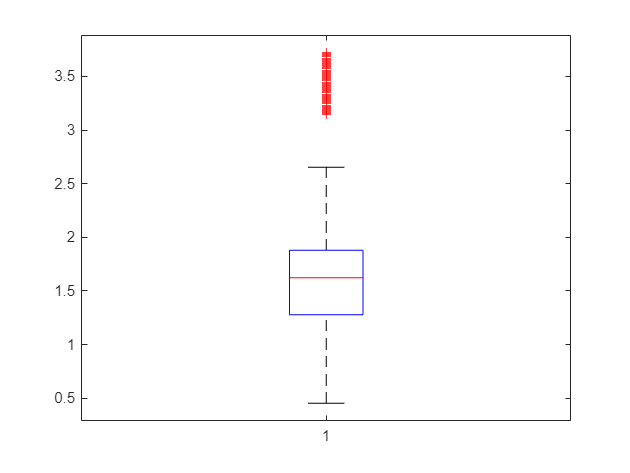

figure;
boxplot(data_fault3.MAP)

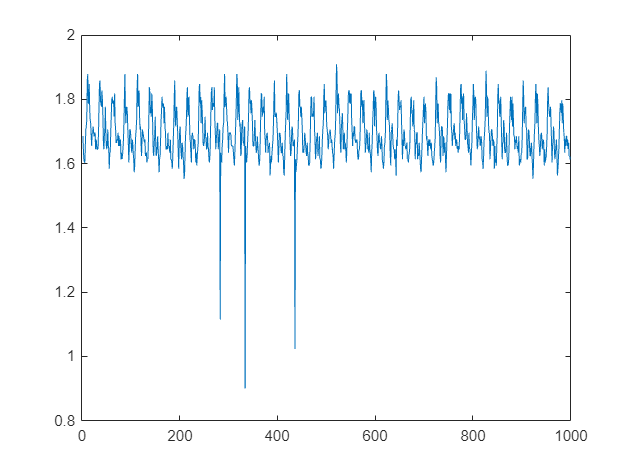

plot(data_fault3.MAP(1:1000,:))

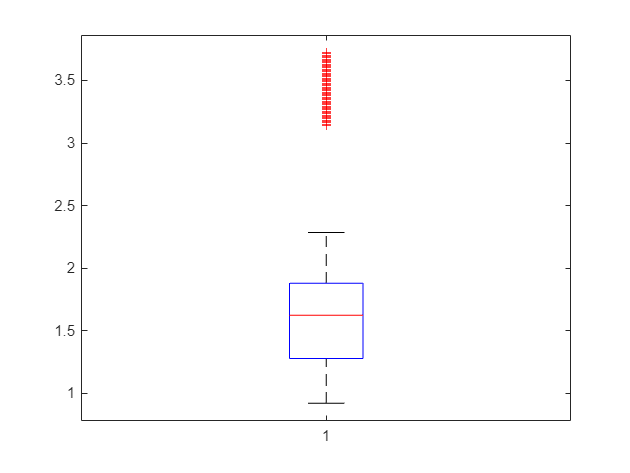

data_faults = {data_fault0, data_fault1, data_fault2, data_fault3};

for i = 1:4
    for t = 1000:1000:10000
        outliers = isoutlier(data_faults{i}(t-999:t, :));
        data_faults{i}(t-999:t, :) = filloutliers(data_faults{i}(t-999:t, :), 'linear');
    end
end

%% Update
data_fault0 = data_faults{1};
data_fault1 = data_faults{2};
data_fault2 = data_faults{3};
data_fault3 = data_faults{4};
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

boxplot(data_fault3.MAP)

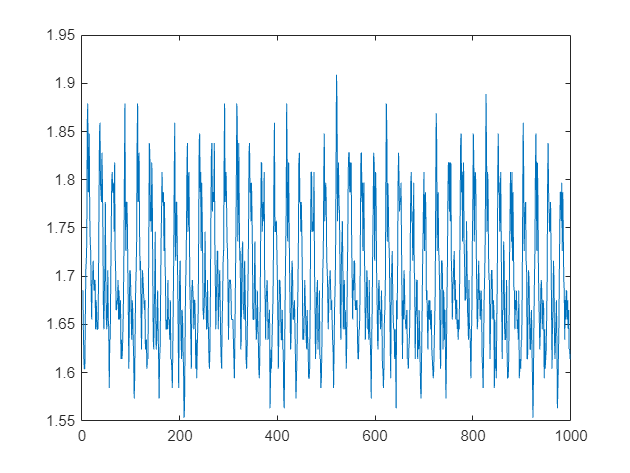

plot(data_fault3.MAP(1:1000,:))

### 2.3. Correlation Check

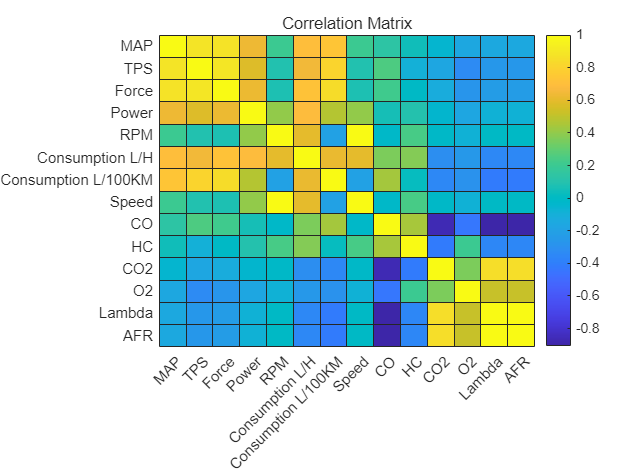

figure;
variable_names = datasets.Properties.VariableNames(2:end);
corr_matrix = corrcoef(table2array(datasets(:, 2:end)));
heatmap(corr_matrix, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Correlation Matrix', 'Colormap', parula);

disp(corr_matrix);

    1.0000    0.8844    0.8803    0.6295    0.2013    0.6979    0.7396    0.2011    0.1343    0.0443   -0.0496   -0.1577   -0.1449   -0.1449
    0.8844    1.0000    0.8916    0.5826    0.0928    0.6480    0.8070    0.0925    0.2538   -0.0987   -0.1641   -0.3309   -0.2619   -0.2619
    0.8803    0.8916    1.0000    0.6214    0.0724    0.7198    0.8484    0.0718    0.2167   -0.0027   -0.1261   -0.2742   -0.2318   -0.2318
    0.6295    0.5826    0.6214    1.0000    0.4035    0.6952    0.4730    0.4058    0.0604    0.1010   -0.0411   -0.1617   -0.0788   -0.0788
    0.2013    0.0928    0.0724    0.4035    1.0000    0.6034   -0.1980    0.9969   -0.0205    0.2362   -0.0156   -0.0801   -0.0038   -0.0037
    0.6979    0.6480    0.7198    0.6952    0.6034    1.0000    0.6141    0.6032    0.3584    0.3748   -0.3133   -0.2521   -0.3479   -0.3478
    0.7396    0.8070    0.8484    0.4730   -0.1980    0.6141    1.0000   -0.1973    0.4413    0.0270   -0.3500   -0.2904   -0.4139   -0.4139
    0.2011   

**연관성 높은 Variables 제거**

corr_threshold = 0.8;
high_corr = abs(corr_matrix) > corr_threshold

high_corr = 14×14 logical 배열
   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   1   0   0   0   0   0   0   0
   1   1   1   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   1   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   1   0   1   0   1   1
   0   0   0   0   0   0   0   0   0   1   0   0   0   0


high_corr = high_corr - eye(size(high_corr));
[rows, cols] = find(high_corr);

correlated_vars = unique(max(rows, cols));
variable_names = datasets.Properties.VariableNames(2:end);
vars_to_remove = variable_names(correlated_vars);

disp(['Removed variables: ', strjoin(vars_to_remove, ', ')]);

Removed variables: TPS, Force, Consumption L/100KM, Speed, CO2, Lambda, AFR


% 높은 연관성을 가진 데이터 제거
% datasets(:, correlated_vars+1)=[];

### 2.4. Min-Max Scaling

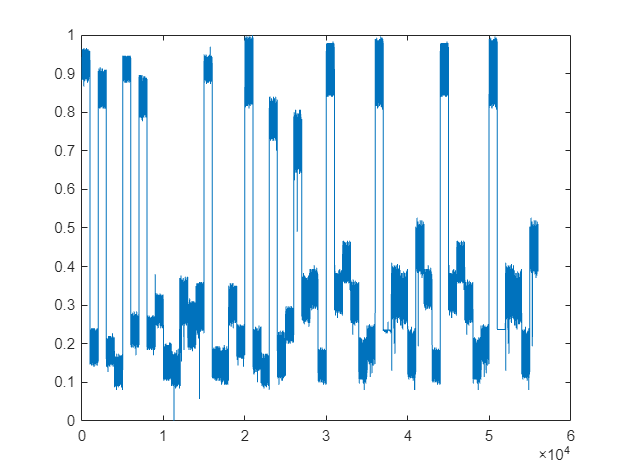

variables = datasets.Properties.VariableNames(2:end);

for i = 1:length(variables)

    datasets.(variables{i}) = normalize(datasets.(variables{i}), 'range');
end
figure;
plot(datasets.MAP);

### 2.5. Data Cutoff

data_fault0 = datasets(1:10000,:);
data_fault1 = datasets(L0+1:L0+10000, :);
data_fault2 = datasets(L0+L1+1:L0+L1+10000, :);
data_fault3 = datasets(L0+L1+L2+1:L0+L1+L2+10000, :);
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

### 2.6. Data Save

writetable(data_fault0, 'data_fault0.xlsx');
writetable(data_fault0, 'data_fault1.xlsx');
writetable(data_fault0, 'data_fault2.xlsx');
writetable(data_fault0, 'data_fault3.xlsx');

### 2.x. 각 Fault별 Correlation Check

data_fault0 : 정상

data_fault1 : Rich Mixture 

- 높은 Fuel Pressure

- Incorrect Sensor Performance

- Defective Injector

- Faulty Pressure Regulator

- Clogged Air Filter

- Clogged Fuel return line

--> MAP(Manifold 내부의 압력), TPS,  

data_fault2 : Lean Mixture

- Incorrect Sensor Performance

- Low fuel Pressure

- Defective Injector

- Faulty Pressure Regulator

data_fault3 : Low Voltage

- Worn Spark plugs

- Faulty Ignition Cables

- Defective Coils

- Faulty sensor wiring

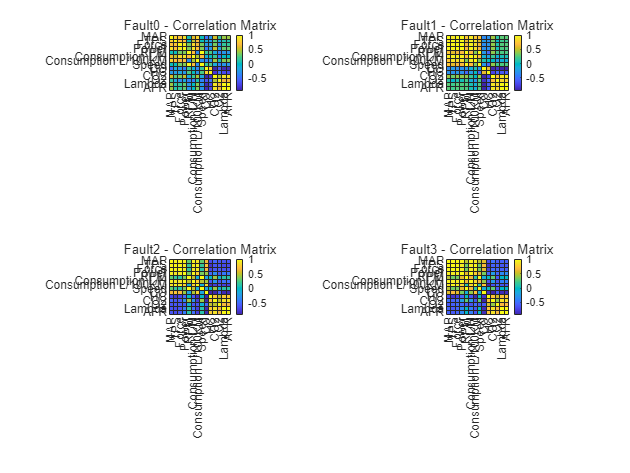

figure;
subplot(2,2,1);
variable_names = data_fault0.Properties.VariableNames(2:end);
corr_matrix_0 = corrcoef(table2array(data_fault0(:, 2:end)));
heatmap(corr_matrix_0, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault0 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,2);
variable_names = data_fault1.Properties.VariableNames(2:end);
corr_matrix_1 = corrcoef(table2array(data_fault1(:, 2:end)));
heatmap(corr_matrix_1, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault1 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,3);
variable_names = data_fault2.Properties.VariableNames(2:end);
corr_matrix_2 = corrcoef(table2array(data_fault2(:, 2:end)));
heatmap(corr_matrix_2, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault2 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,4);
variable_names = data_fault3.Properties.VariableNames(2:end);
corr_matrix_3 = corrcoef(table2array(data_fault3(:, 2:end)));
heatmap(corr_matrix_3, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault3 - Correlation Matrix', 'Colormap', parula);

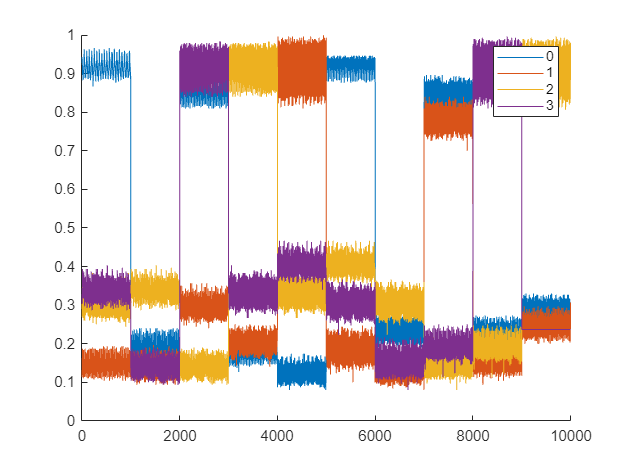

figure;
hold on;
plot(data_fault0.MAP);
plot(data_fault1.MAP);
plot(data_fault2.MAP);
plot(data_fault3.MAP);
hold off
legend('0', '1', '2', '3');

### MOGP

학습 데이터 준비

% figure;
% hold on;
% for i = 2:width(datasets)
%     plot(table2array(datasets(:,i)))
% end
% hold off;
% legend(datasets.Properties.VariableNames(2:end))

### GPR (Gaussian Process Regression)을 통해 여러 개의 입력 변수로 다변량 출력 변수를 추정하고자 함. 그러나 해당 데이터는 노이즈로 인해 큰 표준편차를 가지고 있어 GPR의 예측 불확실성이 커질 수 밖에 없어 이를 방지하고자 Moving Average Filter로 노이즈 제거를 진행함.

WindowSize = 10;
kernel = ones(1, WindowSize) / WindowSize;
datasets(:,1)

ans =     0.0940
    0.1883
    0.2819
    0.3749
    0.4689
    0.5612
    0.6539
    0.7465
    0.8391
    0.9311


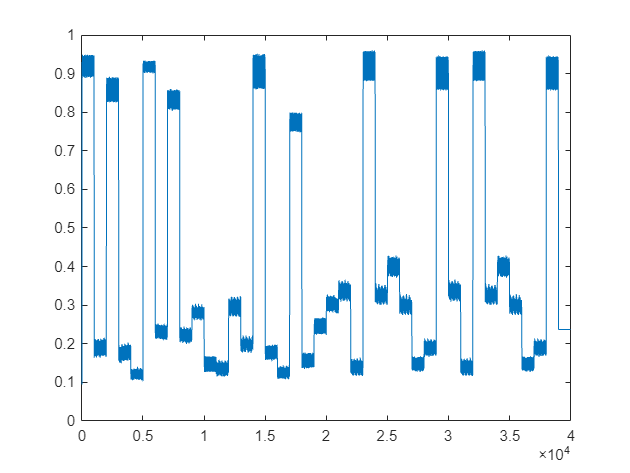

for i = 2:width(datasets)
    datasets = filter(kernel, 1, datasets(:,i});
end

plot(datasets)

% 전체 데이터 크기
total_size = 10000;  % data_fault0, data_fault1 등에서 사용할 총 데이터 크기

selected_n = 3000;

train_n = selected_n*0.8;
test_n = selected_n*0.2;

% 0. 랜덤 샘플링을 위한 인덱스 생성 (Train Set과 Test Set이 중복되지 않도록)
% 각 Fault 유형에서 Train Set과 Test Set의 인덱스를 랜덤하게 뽑음
idx_fault0 = randperm(total_size);
train_idx_fault0 = idx_fault0(1:train_n);  % Train Set 인덱스 (2400개)
test_idx_fault0 = idx_fault0(train_n+1:train_n+test_n);  % Test Set 인덱스 (2400개)

idx_fault1 = randperm(total_size);
train_idx_fault1 = idx_fault1(1:train_n);  % Train Set 인덱스 (2400개)
test_idx_fault1 = idx_fault1(train_n+1:train_n+test_n);  % Test Set 인덱스 (2400개)

idx_fault2 = randperm(total_size);
train_idx_fault2 = idx_fault2(1:train_n);  % Train Set 인덱스 (2400개)
test_idx_fault2 = idx_fault2(train_n+1:train_n+test_n);  % Test Set 인덱스 (2400개)

idx_fault3 = randperm(total_size);
train_idx_fault3 = idx_fault3(1:train_n);  % Train Set 인덱스 (2400개)
test_idx_fault3 = idx_fault3(train_n+1:train_n+test_n);  % Test Set 인덱스 (2400개)

% 1. 각 Fault 유형에서 Train Set과 Test Set의 샘플을 랜덤하게 추출

% Train Set (총 9600개의 샘플)
MAP_train = [data_fault0.MAP(train_idx_fault0); data_fault1.MAP(train_idx_fault1); data_fault2.MAP(train_idx_fault2); data_fault3.MAP(train_idx_fault3)];
TPS_train = [data_fault0.TPS(train_idx_fault0); data_fault1.TPS(train_idx_fault1); data_fault2.TPS(train_idx_fault2); data_fault3.TPS(train_idx_fault3)];
Force_train = [data_fault0.Force(train_idx_fault0); data_fault1.Force(train_idx_fault1); data_fault2.Force(train_idx_fault2); data_fault3.Force(train_idx_fault3)];
Power_train = [data_fault0.Power(train_idx_fault0); data_fault1.Power(train_idx_fault1); data_fault2.Power(train_idx_fault2); data_fault3.Power(train_idx_fault3)];
RPM_train = [data_fault0.RPM(train_idx_fault0); data_fault1.RPM(train_idx_fault1); data_fault2.RPM(train_idx_fault2); data_fault3.RPM(train_idx_fault3)];
ConsumptionLH_train = [data_fault0.("Consumption L/H")(train_idx_fault0); data_fault1.("Consumption L/H")(train_idx_fault1); data_fault2.("Consumption L/H")(train_idx_fault2); data_fault3.("Consumption L/H")(train_idx_fault3)];
ConsumptionL100_train = [data_fault0.("Consumption L/100KM")(train_idx_fault0); data_fault1.("Consumption L/100KM")(train_idx_fault1); data_fault2.("Consumption L/100KM")(train_idx_fault2); data_fault3.("Consumption L/100KM")(train_idx_fault3)];
Speed_train = [data_fault0.Speed(train_idx_fault0); data_fault1.Speed(train_idx_fault1); data_fault2.Speed(train_idx_fault2); data_fault3.Speed(train_idx_fault3)];

CO_train = [data_fault0.CO(train_idx_fault0); data_fault1.CO(train_idx_fault1); data_fault2.CO(train_idx_fault2); data_fault3.CO(train_idx_fault3)];
HC_train = [data_fault0.HC(train_idx_fault0); data_fault1.HC(train_idx_fault1); data_fault2.HC(train_idx_fault2); data_fault3.HC(train_idx_fault3)];
O2_train = [data_fault0.O2(train_idx_fault0); data_fault1.O2(train_idx_fault1); data_fault2.O2(train_idx_fault2); data_fault3.O2(train_idx_fault3)];
CO2_train = [data_fault0.CO2(train_idx_fault0); data_fault1.CO2(train_idx_fault1); data_fault2.CO2(train_idx_fault2); data_fault3.CO2(train_idx_fault3)];
Lambda_train = [data_fault0.Lambda(train_idx_fault0); data_fault1.Lambda(train_idx_fault1); data_fault2.Lambda(train_idx_fault2); data_fault3.Lambda(train_idx_fault3)];
AFR_train = [data_fault0.AFR(train_idx_fault0); data_fault1.AFR(train_idx_fault1); data_fault2.AFR(train_idx_fault2); data_fault3.AFR(train_idx_fault3)];

% Test Set (총 9600개의 샘플)
MAP_test = [data_fault0.MAP(test_idx_fault0); data_fault1.MAP(test_idx_fault1); data_fault2.MAP(test_idx_fault2); data_fault3.MAP(test_idx_fault3)];
TPS_test = [data_fault0.TPS(test_idx_fault0); data_fault1.TPS(test_idx_fault1); data_fault2.TPS(test_idx_fault2); data_fault3.TPS(test_idx_fault3)];
Force_test = [data_fault0.Force(test_idx_fault0); data_fault1.Force(test_idx_fault1); data_fault2.Force(test_idx_fault2); data_fault3.Force(test_idx_fault3)];
Power_test = [data_fault0.Power(test_idx_fault0); data_fault1.Power(test_idx_fault1); data_fault2.Power(test_idx_fault2); data_fault3.Power(test_idx_fault3)];
RPM_test = [data_fault0.RPM(test_idx_fault0); data_fault1.RPM(test_idx_fault1); data_fault2.RPM(test_idx_fault2); data_fault3.RPM(test_idx_fault3)];
ConsumptionLH_test = [data_fault0.("Consumption L/H")(test_idx_fault0); data_fault1.("Consumption L/H")(test_idx_fault1); data_fault2.("Consumption L/H")(test_idx_fault2); data_fault3.("Consumption L/H")(test_idx_fault3)];
ConsumptionL100_test = [data_fault0.("Consumption L/100KM")(test_idx_fault0); data_fault1.("Consumption L/100KM")(test_idx_fault1); data_fault2.("Consumption L/100KM")(test_idx_fault2); data_fault3.("Consumption L/100KM")(test_idx_fault3)];
Speed_test = [data_fault0.Speed(test_idx_fault0); data_fault1.Speed(test_idx_fault1); data_fault2.Speed(test_idx_fault2); data_fault3.Speed(test_idx_fault3)];

CO_test = [data_fault0.CO(test_idx_fault0); data_fault1.CO(test_idx_fault1); data_fault2.CO(test_idx_fault2); data_fault3.CO(test_idx_fault3)];
HC_test = [data_fault0.HC(test_idx_fault0); data_fault1.HC(test_idx_fault1); data_fault2.HC(test_idx_fault2); data_fault3.HC(test_idx_fault3)];
O2_test = [data_fault0.O2(test_idx_fault0); data_fault1.O2(test_idx_fault1); data_fault2.O2(test_idx_fault2); data_fault3.O2(test_idx_fault3)];
CO2_test = [data_fault0.CO2(test_idx_fault0); data_fault1.CO2(test_idx_fault1); data_fault2.CO2(test_idx_fault2); data_fault3.CO2(test_idx_fault3)];
Lambda_test = [data_fault0.Lambda(test_idx_fault0); data_fault1.Lambda(test_idx_fault1); data_fault2.Lambda(test_idx_fault2); data_fault3.Lambda(test_idx_fault3)];
AFR_test = [data_fault0.AFR(test_idx_fault0); data_fault1.AFR(test_idx_fault1); data_fault2.AFR(test_idx_fault2); data_fault3.AFR(test_idx_fault3)];

% 2. Fault 라벨 (0 = 정상, 1 = Rich Mixture, 2 = Lean Mixture, 3 = Low Voltage)도 랜덤하게 추출
FaultLabels_train = [data_fault0.Fault(train_idx_fault0); data_fault1.Fault(train_idx_fault1); data_fault2.Fault(train_idx_fault2); data_fault3.Fault(train_idx_fault3)];
FaultLabels_test = [data_fault0.Fault(test_idx_fault0); data_fault1.Fault(test_idx_fault1); data_fault2.Fault(test_idx_fault2); data_fault3.Fault(test_idx_fault3)];

% 3. Train Set과 Test Set 결합
X_train = [MAP_train, TPS_train, Force_train, Power_train, RPM_train, ConsumptionLH_train, ConsumptionL100_train, Speed_train];
Y_train = [CO_train, HC_train, CO2_train, O2_train, Lambda_train, AFR_train];

X_test = [MAP_test, TPS_test, Force_test, Power_test, RPM_test, ConsumptionLH_test, ConsumptionL100_test, Speed_test];
Y_test = [CO_test, HC_test, CO2_test, O2_test, Lambda_test, AFR_test];


tic
% 5. MOGP 대신 각 출력 변수에 대해 가우시안 프로세스 회귀 모델 학습 (학습 데이터 사용)
gprMdl_CO = fitrgp(X_train, Y_train(:, 1));  % CO 예측 모델
gprMdl_HC = fitrgp(X_train, Y_train(:, 2));  % HC 예측 모델
gprMdl_CO2 = fitrgp(X_train, Y_train(:, 3));  % O2 예측 모델
gprMdl_O2 = fitrgp(X_train, Y_train(:, 4));  % O2 예측 모델
gprMdl_Lambda = fitrgp(X_train, Y_train(:, 5));  % O2 예측 모델
gprMdl_AFR = fitrgp(X_train, Y_train(:, 6));  % Lambda 예측 모델
toc

경과 시간은 43.055024초입니다.


resubLoss(gprMdl_AFR)

ans = 0.0049

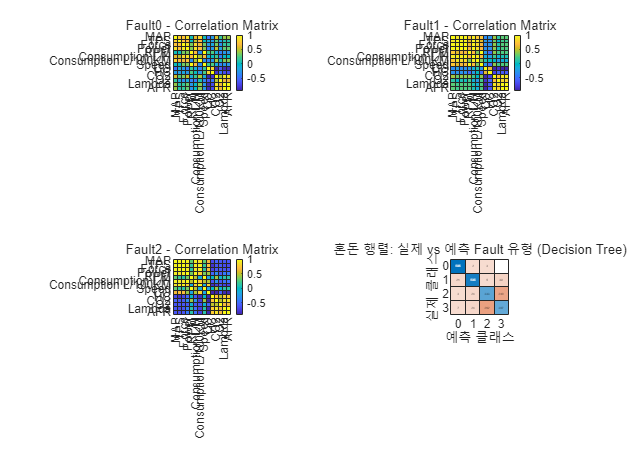


% 6. 테스트 데이터에 대해 출력 변수 예측
test_size = length(Y_test);

Y_pred_test = zeros(test_size, 6);  % 예측된 출력 값을 저장할 행렬

for i = 1:test_size
    new_X = X_test(i, :);  % 테스트 데이터 샘플 가져오기
    
    % 예측 수행
    Y_pred_test(i, 1) = predict(gprMdl_CO, new_X);
    Y_pred_test(i, 2) = predict(gprMdl_HC, new_X);
    Y_pred_test(i, 3) = predict(gprMdl_CO2, new_X);
    Y_pred_test(i, 4) = predict(gprMdl_O2, new_X);
    Y_pred_test(i, 5) = predict(gprMdl_Lambda, new_X);
    Y_pred_test(i, 6) = predict(gprMdl_AFR, new_X);
end

% 7. Decision Tree 모델을 사용하여 Fault 분류 (학습 데이터 사용)
decisionTreeMdl = fitctree(Y_train, FaultLabels_train);  % 다중 클래스 Decision Tree 모델 학습

% 8. 예측된 출력 변수들로 테스트 데이터의 Fault 유형 예측
predicted_faults = predict(decisionTreeMdl, Y_pred_test);

% 9. 혼돈 행렬 생성 및 시각화
confusionchart(FaultLabels_test, predicted_faults);
title('혼돈 행렬: 실제 vs 예측 Fault 유형 (Decision Tree)');


accuracy = sum(predicted_faults == FaultLabels_test) / length(FaultLabels_test)

accuracy = 0.7375

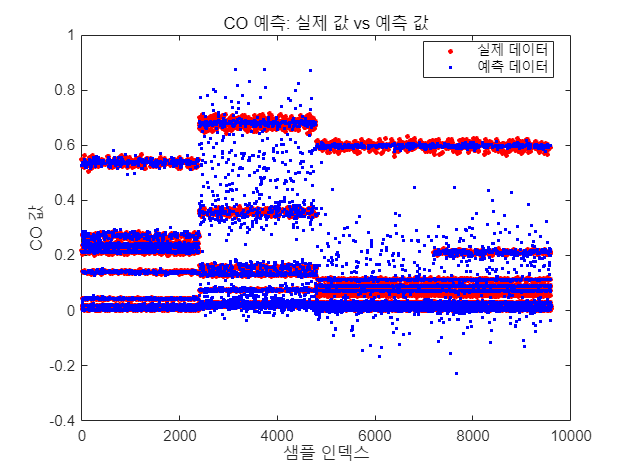

% 학습 데이터에 대해 CO 예측
ypred_CO_train = predict(gprMdl_CO, X_train);

% 실제 CO 값 (Y_train의 첫 번째 열)
actual_CO_train = Y_train(:, 1);

train_size = length(Y_train);

% 예측된 값과 실제 값을 비교하는 그래프 생성
figure();
plot(1:train_size, actual_CO_train, 'r.', 'MarkerSize', 10);  % 실제 CO 값
hold on;
plot(1:train_size, ypred_CO_train, 'b.', 'LineWidth', 1.5);  % 예측된 CO 값
xlabel('샘플 인덱스');
ylabel('CO 값');
legend({'실제 데이터', '예측 데이터'}, 'Location', 'Best');
title('CO 예측: 실제 값 vs 예측 값');
hold off;